% Load ABR data
clear all;
clc;
load('ABR_rec.mat');

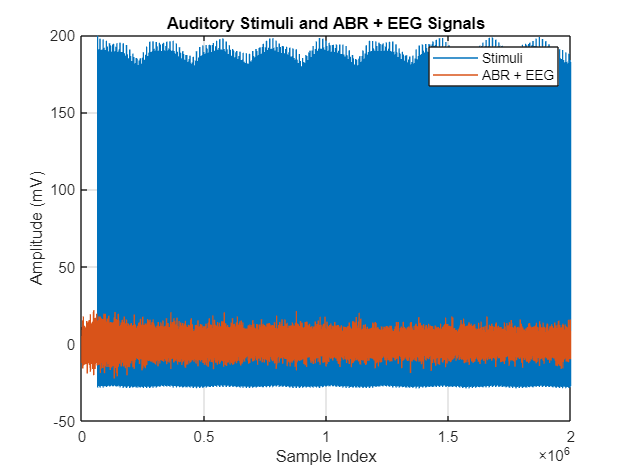

figure;
plot(ABR_rec);  % Plot both columns
legend('Stimuli', 'ABR + EEG');  % Add legend for clarification
xlabel('Sample Index');
ylabel('Amplitude (mV)');
title('Auditory Stimuli and ABR + EEG Signals');
grid on;

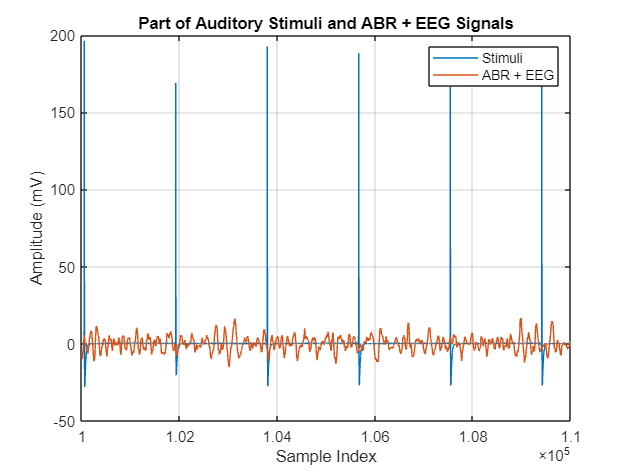

%plot part of the signal
start_sample = 100000;
Number_of_samples = 10000;

range = start_sample : start_sample + Number_of_samples - 1;

figure;
plot(range, ABR_rec(range, :));  % Plot only the first 10 ms
legend('Stimuli', 'ABR + EEG');  % Add legend for clarification
xlabel('Sample Index');
ylabel('Amplitude (mV)');
title('Part of Auditory Stimuli and ABR + EEG Signals');
grid on;

% Voltage threshold
thresh = find(ABR_rec(:,1) > 50);

stim_point = [];
j = 1;
for i = 1 : length(thresh) - 1
    if thresh(i+1) - thresh(i) > 1
        stim_point(j,1) = thresh(i+1);
        j = j + 1;
    end
end

% Window ABR epochs
epochs = [];
j = 0;
for i = 1 : length(stim_point)
    j = j + 1;
    epochs(:,j) = ABR_rec((stim_point(i) - 80 : stim_point(i) + 399), 2);
end

% Calculate the ensemble average 
ensmbl_avg = mean(epochs(: , (1 : length(stim_point))) , 2);

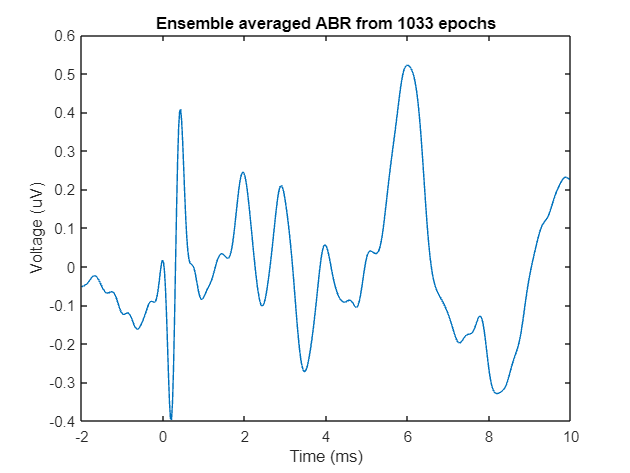

% Plot the ensemble averaged ABR waveform
figure;
plot((-80:399)/40, ensmbl_avg);
xlabel('Time (ms)')
ylabel('Voltage (uV)')
title(['Ensemble averaged ABR from ',num2str(length(epochs)),' epochs'])

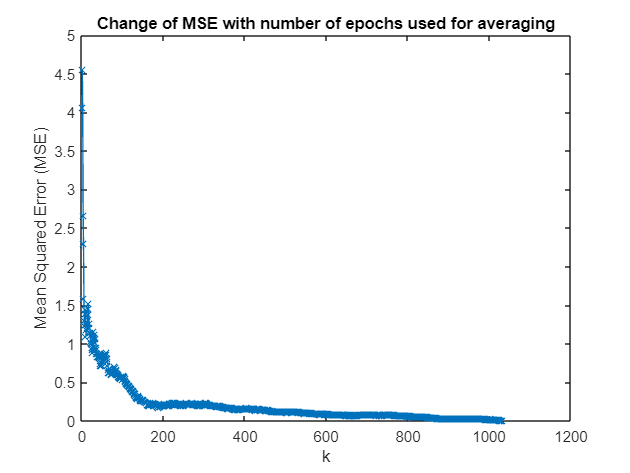

% Improvement of the SNR

% Calculate progressive MSEs
MSEs = calculate_progressive_MSEs(ensmbl_avg, epochs, length(stim_point));

% Plot the graph of MSEk against k 
figure();
plot(1:length(stim_point), MSEs, '-x');
xlabel('k');
ylabel('Mean Squared Error (MSE)');
title('Change of MSE with number of epochs used for averaging')

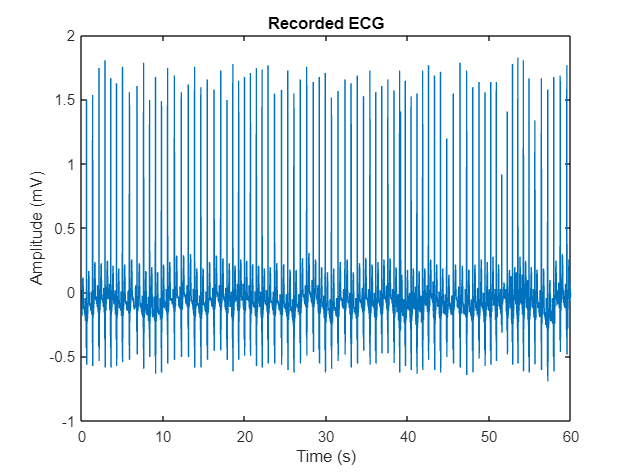

% Signal with repetitive patterns
load("ECG_rec.mat");

% Plot ECG dat
fs_ECG = 128;
time = (0 : length(ECG_rec)-1)/fs_ECG;

plot (time, ECG_rec);
xlabel("Time (s)");
ylabel("Amplitude (mV)");
title("Recorded ECG");

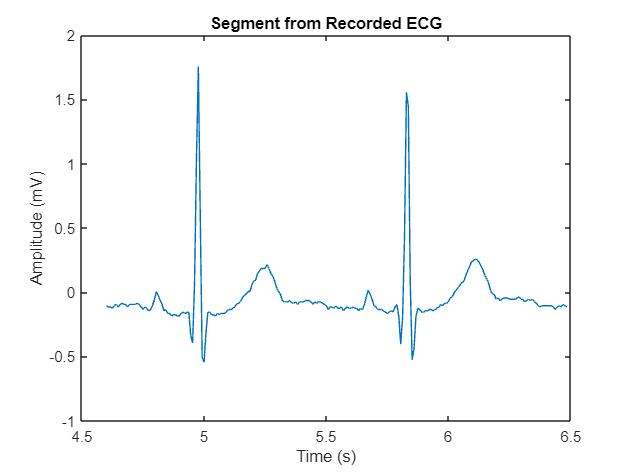


% A segment from recorded ECG
time_ = 590:831;

plot (time(time_), ECG_rec(time_));
xlabel("Time (s)");
ylabel("Amplitude (mV)");
title("Segment from Recorded ECG");

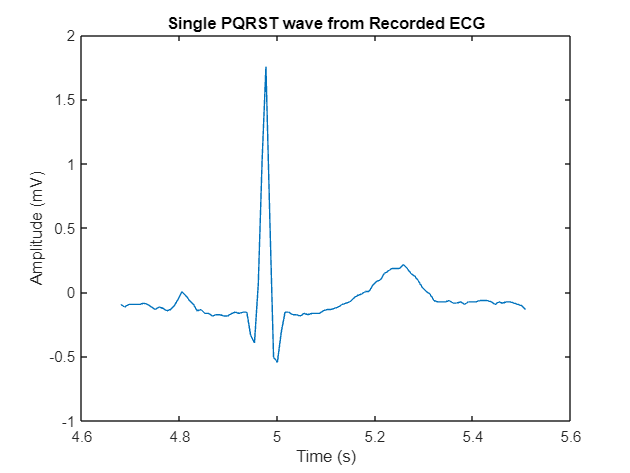

% Extract a single PQRST waveform
time__ = 600:706; % took 106 samples as the length RR = 60/HR = 60/72

plot (time(time__), ECG_rec(time__));
xlabel("Time (s)");
ylabel("Amplitude (mV)");
title("Single PQRST wave from Recorded ECG");


ECG_template = ECG_rec(time__);

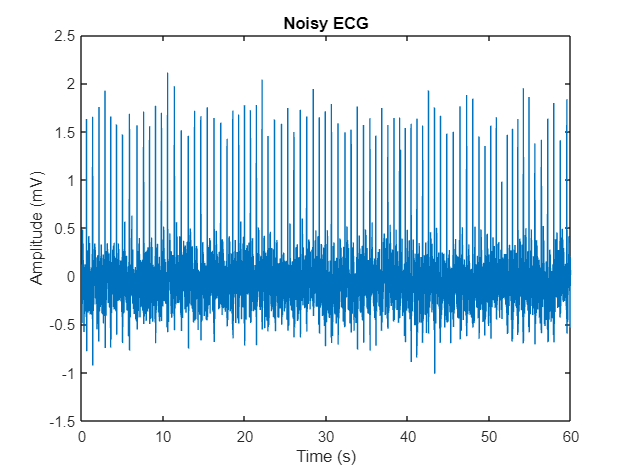

% Add Gaussian white noise
SNR = 5;
rng(0);
nECG = awgn(ECG_rec, SNR, "measured");

plot (time, nECG);
xlabel("Time (s)");
ylabel("Amplitude (mV)");
title("Noisy ECG");

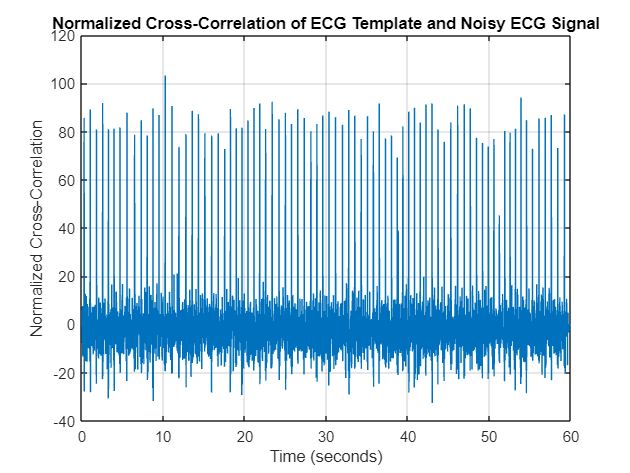

% Calculate normalised cross-correlation

% Normalize noisy ECG signal
nECG_normalized = (nECG-mean(nECG))/std(nECG);

% Normalized ECG template
ECG_template_normalized = (ECG_template - mean(ECG_template))/std(ECG_template);

[cross_corr, lags] = xcorr(nECG_normalized, ECG_template_normalized);

% Normalised cross-correlation values against the adjusted lag axis converted to time axis.
adjusted_lag_axis = lags(length(nECG):length(lags)); % adjust the lag
cross_corr = cross_corr(length(nECG):length(cross_corr)); % adjust the cross_corr
time_axis = adjusted_lag_axis/fs_ECG;

plot(time_axis, cross_corr);
xlabel('Time (seconds)');
ylabel('Normalized Cross-Correlation');
title('Normalized Cross-Correlation of ECG Template and Noisy ECG Signal');
grid on;

% Voltage threshold
ECG_thresh = find(cross_corr > 40);

% Ectract R peaks starting points
R_peaks = [];

j = 1;
for i = 1 : length(ECG_thresh)-1
    if ECG_thresh(i+1) - ECG_thresh(i) > 1
        R_peaks(j,1) = ECG_thresh(i+1);
        j = j + 1;
    end
end

% Window ECG waves accorging to the R peaks
ECG_waves = [];

j = 0;
for i = 1 : length(R_peaks)
    j = j + 1;
    ECG_waves(:,j) = nECG((R_peaks(i,1) - 10 : R_peaks(i,1) + 96));
end

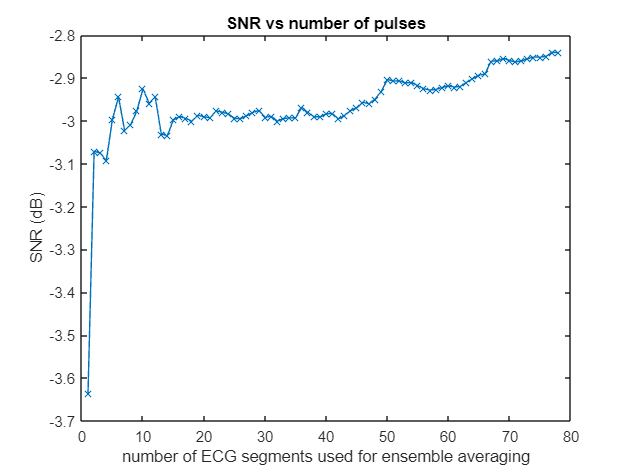

% Calculate and plot the improvement in SNR as the number of ECG pulses included in 
% the ensemble average is increased.

SNRs = [];

for i = 1 : length(R_peaks)
    y_i = mean(ECG_waves(:,(1:i)), 2);
    SNR_i = calculate_SNR(ECG_template', y_i);
    SNRs(i,1) = SNR_i;
end

figure;
plot(1:length(R_peaks), SNRs, '-x');
xlabel('number of ECG segments used for ensemble averaging')
ylabel('SNR (dB)')
title("SNR vs number of pulses")

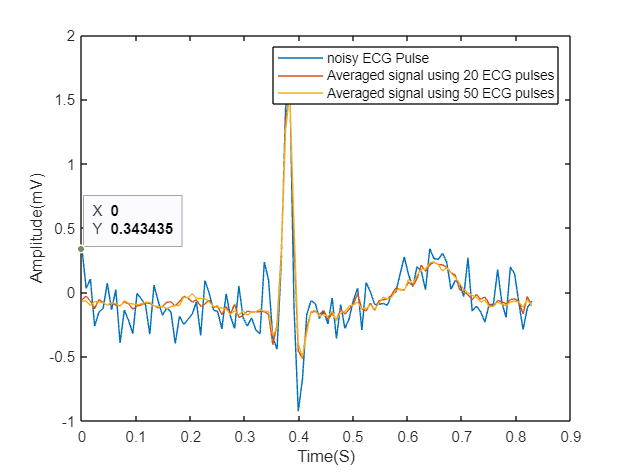

% Plot and compare (in the one graph), a selected noisy ECG pulse and two arbitrary 
% selected ensemble averaged ECG pulses.
figure;
ensmbl_avg_ECG_1 = mean(ECG_waves(:,(1:20)),2);
ensmbl_avg_ECG_2 = mean(ECG_waves(:,(1:50)),2);
plot((0:106)/fs_ECG, ECG_waves(:,1), (0:106)/fs_ECG, ensmbl_avg_ECG_1, (0:106)/fs_ECG, ensmbl_avg_ECG_2);
legend('noisy ECG Pulse', 'Averaged signal using 20 ECG pulses', 'Averaged signal using 50 ECG pulses');
xlabel('Time(S)');
ylabel('Amplitude(mV)');

disp(length(ensmbl_avg_ECG_2))

   107



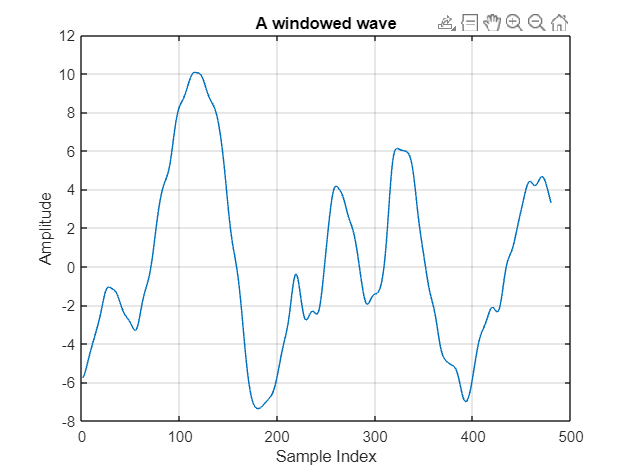

% Plot the first wave from the epochs matrix
figure;
plot(epochs(:,1));  % ECG_waves(:,1) refers to the first column (first ECG wave)
xlabel('Sample Index');
ylabel('Amplitude');
title('A windowed wave');
grid on;

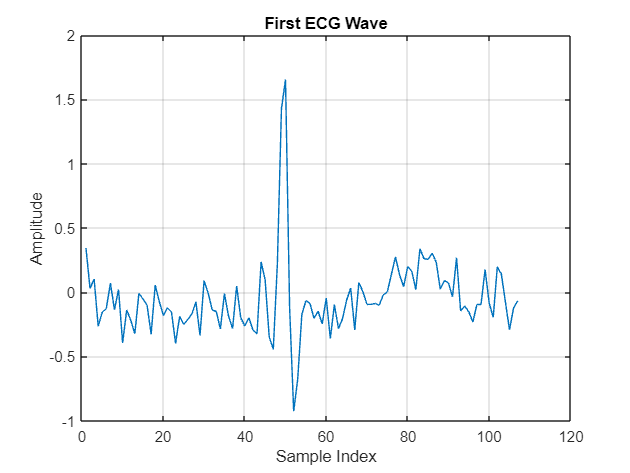


% Plot the first ECG wave from the ECG_waves matrix
figure;
plot(ECG_waves(:,1));  % ECG_waves(:,1) refers to the first column (first ECG wave)
xlabel('Sample Index');
ylabel('Amplitude');
title('First ECG Wave');
grid on;